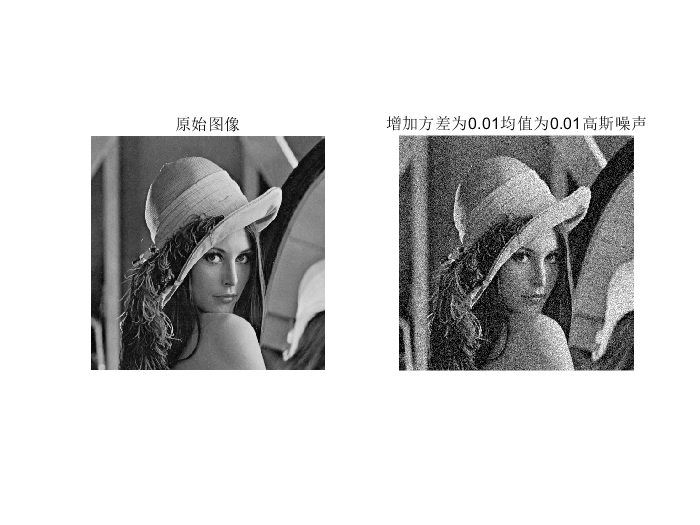

clc;
clear;
m=0.01;var1=0.01;
pi1=imread('lena.bmp');
po1=imnoise(pi1,'gaussian',m,var1);
figure;
subplot(1,2,1)
imshow(pi1)
title('原始图像');
subplot(1,2,2)
imshow(po1)
title(['增加方差为',num2str(m),'均值为',num2str(var1),'高斯噪声']);
% saveas(gcf,'1.png')

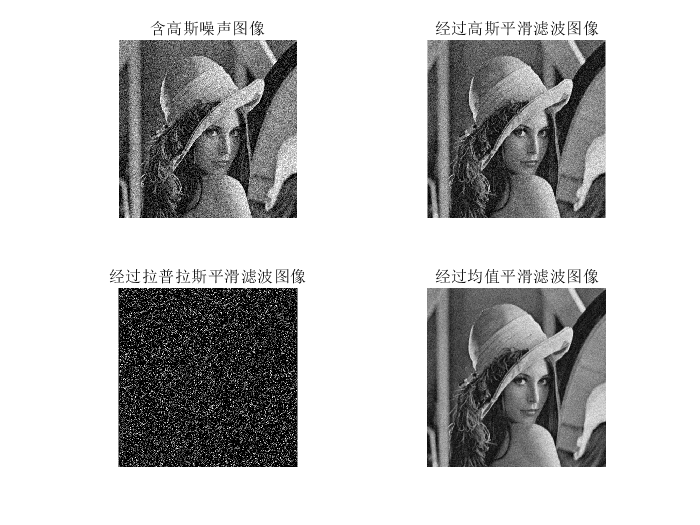


w1=fspecial('gaussian');%高斯平滑滤波
po2=imfilter(po1,w1);



w2=fspecial('laplacian');
po3=imfilter(po1,w2);



w3=fspecial('average');
po4=imfilter(po1,w3);

figure;
subplot(2,2,1)
imshow(po1)
title('含高斯噪声图像');

subplot(2,2,2)
imshow(po2)
title('经过高斯平滑滤波图像');

subplot(2,2,3)
imshow(po3)
title('经过拉普拉斯平滑滤波图像');

subplot(2,2,4)
imshow(po4)
title('经过均值平滑滤波图像');

% saveas(gcf,'2.png')